# DeconvolutionLab2 pruebas

javaaddpath(['C:\Users\biagi\Documents\MATLAB\DeconvolutionLab_2.jar']);

_______________________________________________________________________________________________________

## Cube of Spherical Beads

img = tiffreadVolume('cubeConvolved.tif');
img_b = tiffreadVolume('PSF.tif');

result = DL2.RL(img, img_b, 30,'-out stack');

Log   	 457,50 us 	  486,0Mb  	 DeconvolutionLab2 2.1.2 (27.06.2018) on Matlab
Log   	 1849,50 us 	  561,3Mb  	 AcademicFFT Added
Log   	 11,82 ms 	  561,8Mb  	 JTransforms not found
Log   	 18,27 ms 	  562,8Mb  	 FFTW Widsom not found in : C:\Users\biagi\Documents\MATLAB\FFTW\
Log   	 20,29 ms 	  562,8Mb  	 FFTW Widsom not found in : C:\Users\biagi\Documents\MATLAB\
Log   	 22,21 ms 	  563,6Mb  	 FFTW found in : C:\Users\biagi\FFTW\
Log   	 107,40 ms 	  181,4Mb  	 Loading library FFTW for amd64 Windows 10 C:\Users\biagi\FFTW\FFTWJNIWin64.dll
Log   	 110,29 ms 	  184,7Mb  	 FFTW Added
Log   	 10,40 us 	  195,8Mb  	 Create Live Real Signal 


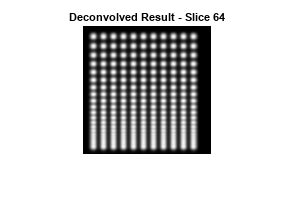

figure;
imshow(result(:,:,64), []);
title('Deconvolved Result - Slice 64');

______________________________________________________________________________________________________

## C. Elegans Embryo

### Canal 1

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath1 = './CElegans-CY3/';
psfPath1 = './PSF-CElegans-CY3';

% Cargar las imágenes en una matriz 3D
image_stack1 = load_image_stack(imagePath1);

psf_stack1 = load_image_stack(psfPath1);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack1 = image_stack1(1:356, 1:336, :);
psf_stack1 = psf_stack1(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack1));

   356   336   104



disp(size(psf_stack1));

   305   305   104



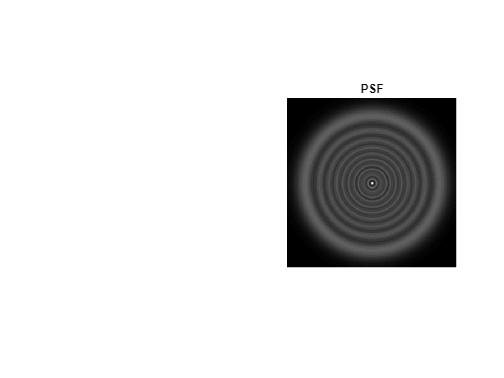

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack1(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel1 = DL2.RL(image_stack1, psf_stack1, 50,'-out stack');

Log   	 2200,00 ns 	  396,2Mb  	 Create Live Real Signal 


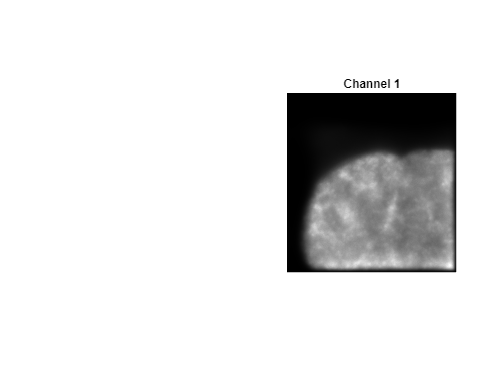

Unrecognized function or variable 'Canal'.


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel1(:, :, 52),[]);

% Añadir título
title('Channel 1');

% Desactivar los ejes
axis off;Canal 2

### Canal 2

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath2 = './CElegans-DAPI/';
psfPath2 = './PSF-CElegans-DAPI/';

% Cargar las imágenes en una matriz 3D
image_stack2 = load_image_stack(imagePath2);
psf_stack2 = load_image_stack(psfPath2);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack2 = image_stack2(1:356, 1:336, :);
psf_stack2 = psf_stack2(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack2));
disp(size(psf_stack2));

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack2(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel2 = DL2.RL(image_stack2, psf_stack2, 50,'-out stack');

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel2(:, :, 52),[]);

% Añadir título
title('Channel 2');

% Desactivar los ejes
axis off;

### Canal 3

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath3 = './CElegans-FITC/';
psfPath3 = './PSF-CElegans-FITC/';

% Cargar las imágenes en una matriz 3D
image_stack3 = load_image_stack(imagePath3);
psf_stack3 = load_image_stack(psfPath3);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack3 = image_stack3(1:356, 1:336, :);
psf_stack3 = psf_stack3(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack3));
disp(size(psf_stack3));


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack3(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel3 = DL2.RL(image_stack3, psf_stack3, 50,'-out stack');


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel3(:, :, 52),[]);

% Añadir título
title('Channel 3');

% Desactivar los ejes
axis off;

### Combinación de canales

% Normalizar los canales (opcional, pero recomendado)
deconvolved_stack_R = normalize(channel1);
deconvolved_stack_G = normalize(channel2);
deconvolved_stack_B = normalize(channel3);

% Combinar los tres canales en una sola matriz 4D (altura, ancho, profundidad, canales)
deconvolved_stack_color = cat(4, deconvolved_stack_R, deconvolved_stack_G, deconvolved_stack_B);

% Visualizar un plano específico de la imagen deconvolucionada en color
figure;

subplot(1, 2, 1);
original_image_R = normalize(image_stack1(:, :, 52));
original_image_G = normalize(image_stack2(:, :, 52));
original_image_B = normalize(image_stack3(:, :, 52));
original_image_color = cat(3, original_image_R, original_image_G, original_image_B);
imshow(original_image_color);
title('Original');
axis off;

subplot(1, 2, 2);
deconvolved_image_color = squeeze(deconvolved_stack_color(:, :, 52, :));  % Convertir 4D a 3D para mostrar
imshow(deconvolved_image_color);
title('Deconvolved');
axis off;

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), class(first_image));
    
    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        image_stack(:, :, i) = imread(fullfile(folder_path, files(i).name));
    end
end

function normalized_image = normalize(image)
    min_val = double(min(image(:)));  % Convertir a double para evitar problemas con uint16
    max_val = double(max(image(:)));
    if min_val == max_val
        normalized_image = zeros(size(image), 'like', image);  % Usar el mismo tipo de datos
    else
        normalized_image = (double(image) - min_val) / (max_val - min_val);
    end
end